# 基于77GHz FMCW 毫米波雷达的SAR成像教程

## 1.项目介绍

In scope of the project, a two-dimensional (2-D) near-field imaging system based on the combination of synthetic aperture radar (SAR) processing techniques and the low-cost system-on-chip millimeter-wave frequency-modulated continuous-wave (FMCW) radars is designed. To create a synthetic aperture over the target scene, a two-axis automatic rail system is built and integrated with Texas Instruments IWR1443 77-GHz millimeter-wave FMCW radar sensor. In this tutorial, simplified signal processing techniques for near-field 2-D image formation is introduced and the specifications of recorded SAR data samples are detailed.

本项目结合合成孔径雷达(SAR)处理技术和低成本系统片上毫米波调频连续波(FMCW)雷达，设计了一套二维(2D)近场成像系统。为了在目标场景上创建合成孔径，建立了一个两轴自动轨道系统，并与德州仪器公司IWR1443 77-GHz毫米波FMCW雷达传感器集成。在本教程中，介绍了近场二维图像形成的简化信号处理技术，并详细介绍了记录的SAR数据样本的规格。

## 2.系统配置和记录数据格式

### 2.1 系统配置

To reconstruct the 2-D image of the scene, data collection is performed by moving the radar along a trajectory in - plane, which creates a rectangular grid of measurement points, as shown in Figure 1. It is assumed that transmitting and receiving antenna are located very close to each other, then they are represented by the mid-point between them. In the established ( , , ) Cartesian coordinate system, - axis, - axis, and - axis denote horizontal, vertical, and range directions, respectively.

为了重建场景的二维图像，将雷达沿着 - 平面的轨迹进行数据采集，形成测点的矩形网格，如图1所示。假设发射天线和接收天线相距很近，则用它们之间的中点表示。在已建立的( ， ， )直角坐标系中， 轴、 轴、 轴分别表示水平、垂直、距离方向。

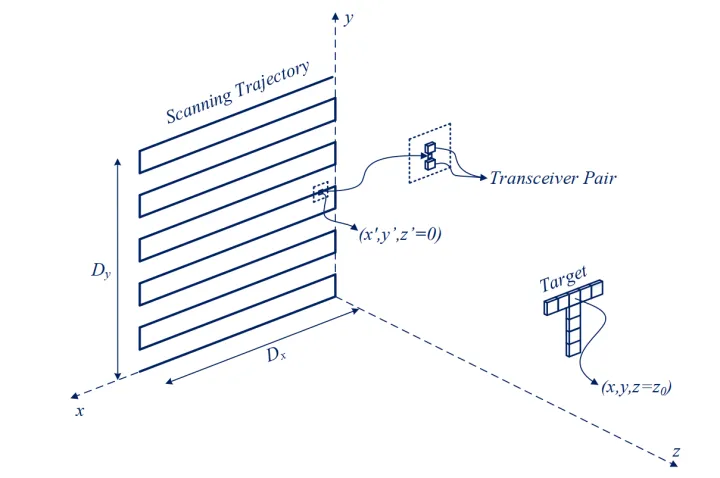

图1 系统配置

As illustrated in the measurement configuration, transceiver is at position ( ′, ′, 0) for a specific measurement instant and a general point on the target placed at the distance 0 from the imaging system is at position ( , , 0). The detailed scanning aperture configuration is shown in Figure 2. Total scan size is and in -axis and - axis, respectively, and the corresponding sampling distance is and .

如测量配置所示，在某一测量瞬间，雷达收发器处于( '， '，0)的位置，目标上距成像系统距离 0的总点处于( ， ， 0)的位置。详细的扫描孔径配置如图2所示。总扫描尺寸在 -轴上为 ， -轴上为 ，对应的采样距离 ， 。

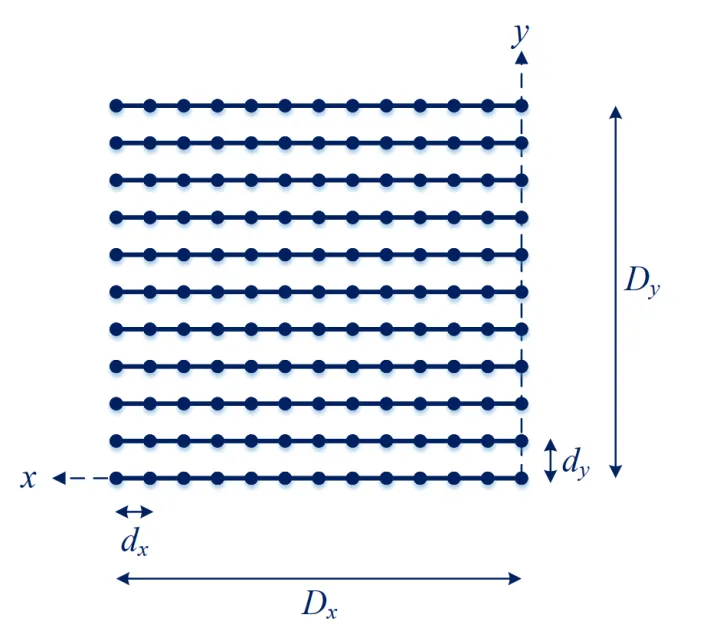

图 2 孔径配置

Chirp paramaters used at the experiments are shown in Figure 3.

实验中使用的chirp参数如图3所示:

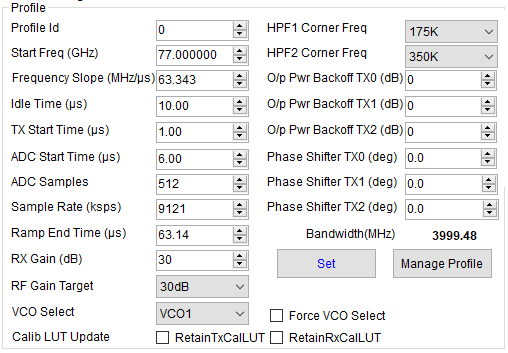

图3 chirp参数

### 2.2 数据记录格式

The 3-D recorded data cube is shown in Figure 4 and properties are detailed below.

3-D记录的数据立方体如图4所示，其属性如下所示。

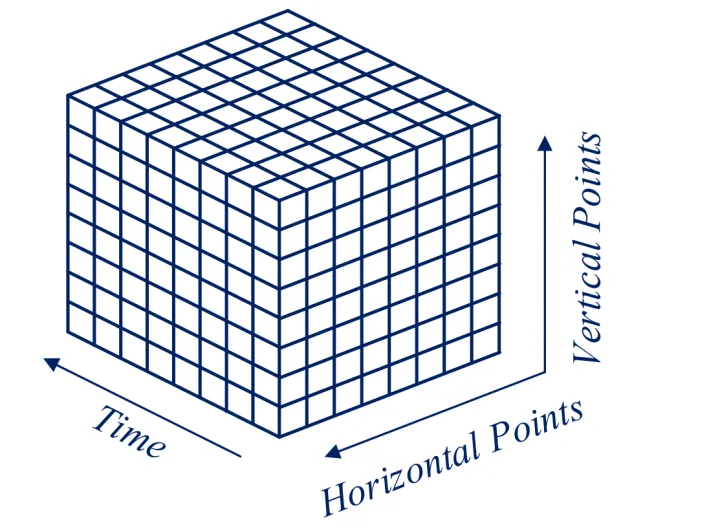

图4 记录数据立方体

rawData3D is an nSample × nVertical × nHorizontal 3-D data matrix. Details of parameters are given below.

rawData3D是一个nSample × nVertical × nHorizontal的三维数据矩阵。参数的细节如下所示。

## 3.简易二维成像算法

After coinciding the target and aperture coordinates, the 2-D reflectivity image can be formulated as

将目标坐标与孔径坐标重合后，二维反射率图像可表示为：


$$f(x,y)=\mathrm{FT}_{2D}^{-1}\left[\mathrm{FT}_{2D}[s(x,y)]\mathrm{FT}_{2D}[h(x,y)]]\right.$$


where $FT_{2D}$ and $FT_{2D}^{- 1}$ denote 2-D Fourier and inverse Fourier transform operations over the - plane, ( , ) is 2-D target reflectivity function, ( , ) is the measured radar signals, and ℎ( , ) is the impulse response or the point spread function of the imaging system calculated for each ( , ) measurement point as：

其中 $FT_{2D}$ and $FT_{2D}^{- 1}$ 表示在 - 平面上的二维傅里叶和傅里叶逆变换运算， ( , ) 是二维目标反射率函数， ( , ) 是测量的雷达信号，并且 ℎ( , ) 是为每个 ( , ) 测量点计算的成像系统的脉冲响应或点扩散函数为：


$$h(x,y)=e^{-j2k\sqrt{x^2+y^2+z^2_0}}$$


The reconstruction algorithm summarized in Figure 5 does not consider any visibility condition. Thus, built-in MATLAB 2-D FFT function can be used directly.

图 5 中总结的重建算法不考虑任何可见性条件。 因此，可以直接使用内置的 MATLAB 2-D FFT 函数。

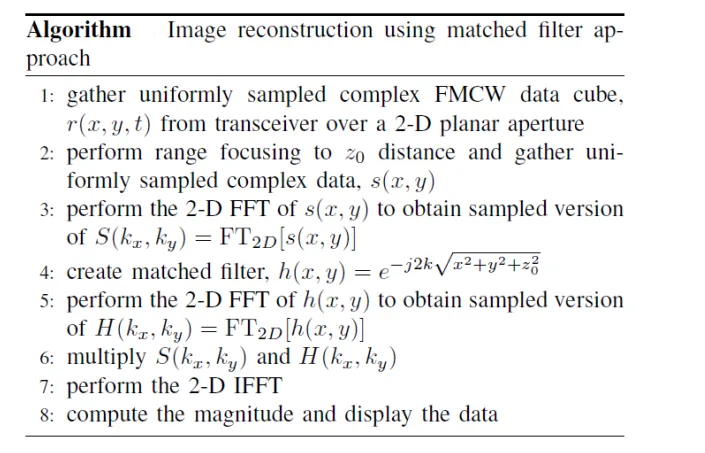

图5 简易成像算法结构

## 4. 采集数据的场景

## 4.1 平面二维目标

The scenario is shown in Figure 6 and properties are detailed below.

该场景如图 6 所示，属性详述如下：

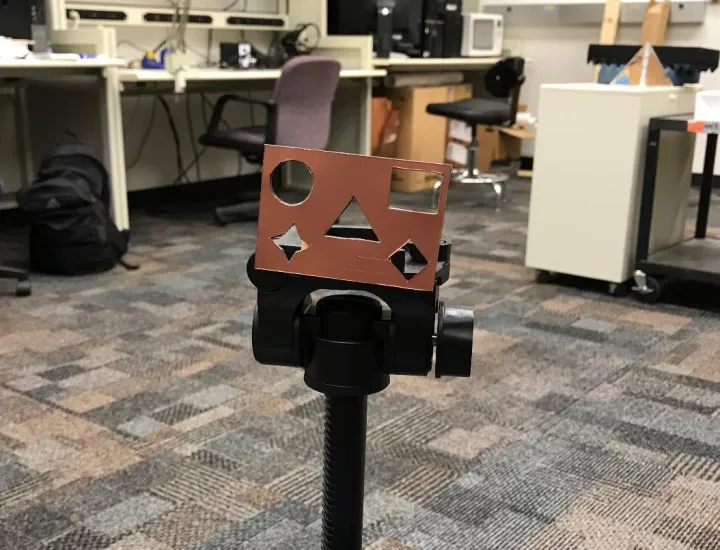

图6 平面2D目标

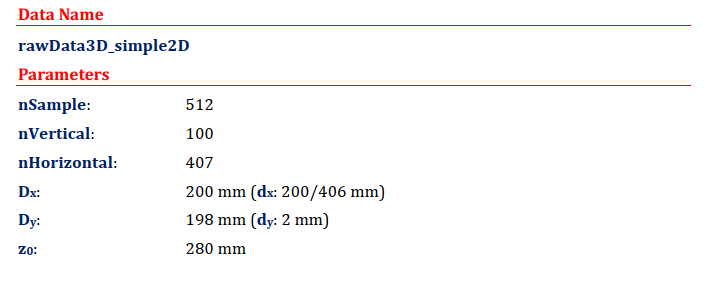

### 4.2 两个平面二维目标隐藏在盒子中

The scenario is shown in Figure 7 and properties are detailed below.

该场景如图7所示，下面详细介绍属性。

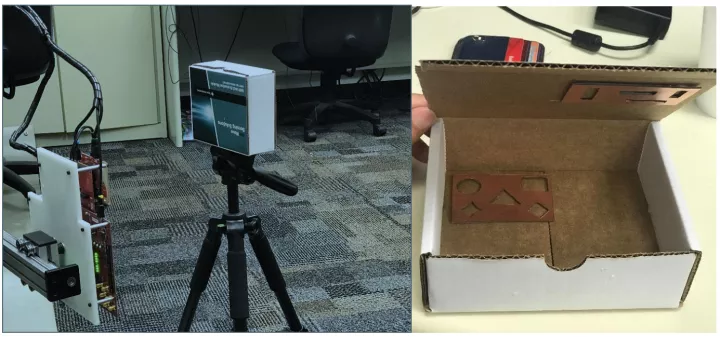

图7 两个平面二维目标隐藏在盒子中

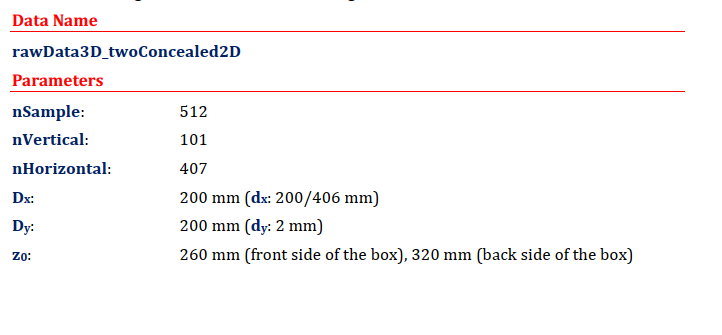

### 4.3 级联隐藏目标

该场景如图8所示，下面详细介绍属性：

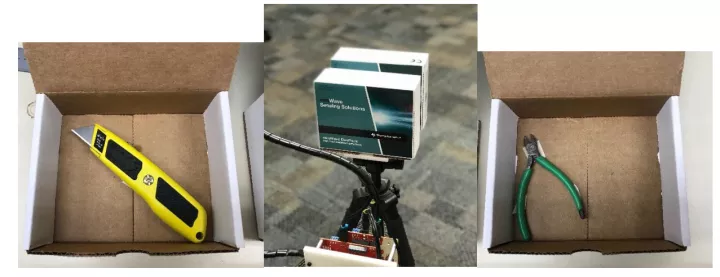

图8 级联隐藏目标

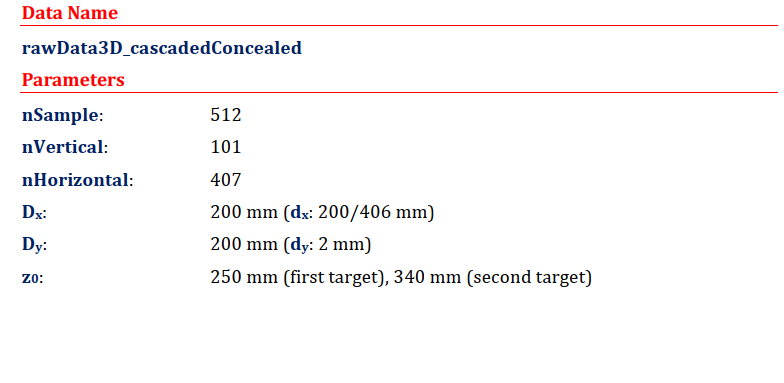

5.处理算法

处理软件的主要脚本如表1所示。

表1 处理脚本

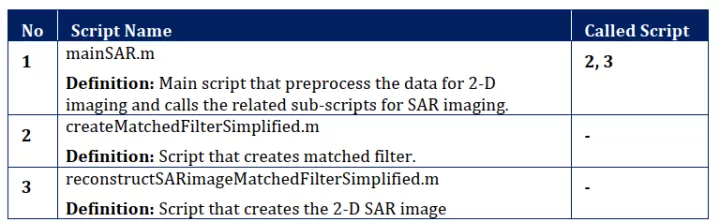

主要代码如下：

该代码块对二维成像的rawData3D进行预处理，并调用其他SAR成像函数。需要根据场景更新以下参数。

%% Load rawData3D
dataName = 'rawData3D_simple2D'; % Change only this line
rawData = load(dataName);
rawData = rawData.(dataName);
%% Define parameters, update based on the scenario
nFFTtime = 1024; % Number of FFT points for Range-FFT
z0 = 280e-3; % Range of target (range of corresponding image slice)
dx = 200/406; % Sampling distance at x (horizontal) axis in mm
dy = 2; % Sampling distance at y (vertical) axis in mm
nFFTspace = 1024; % Number of FFT points for Spatial-FFT

下面一行调用匹配的过滤器创建函数：

%% Create Matched Filter
matchedFilter =
createMatchedFilterSimplified(nFFTspace,dx,nFFTspace,dy,z0*1e3);

下面一行调用图像重建函数，imSize参数可以更改：

%% Create SAR Image
imSize = 200; % Size of image area in mm
sarImage = reconstructSARimageMatchedFilterSimplified(sarData,matchedFilter,dx,dy,imSize
);

匹配滤波函数：matchedFilter = createMatchedFilterSimplified(xPointM,xStepM,yPointM,yStepM,zTarget)

这个函数创建二维匹配的滤波器。输入参数和输出详细如下:

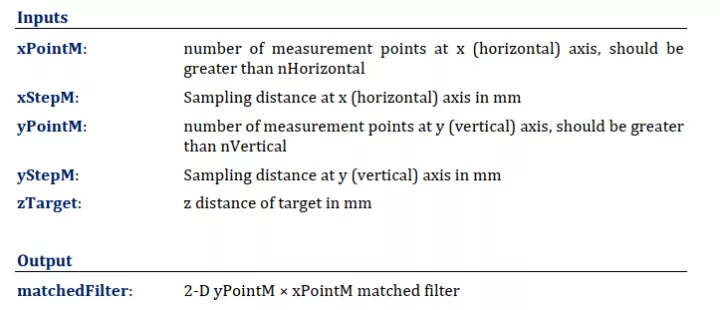

SAR成像函数：sarImage = reconstructSARimageMatchedFilterSimplified(sarData,matchedFilter,xStepM,yStep M,xySizeT)

这个函数创建二维SAR图像。输入参数和输出详细如下:

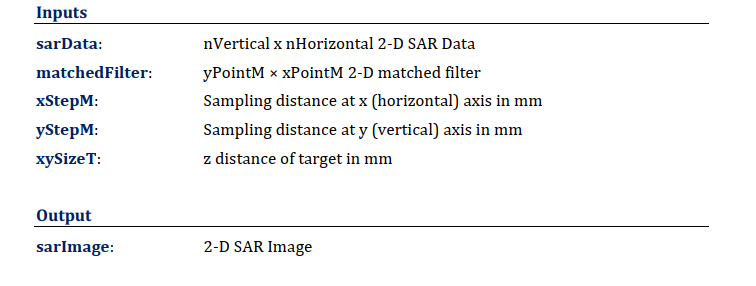

### 6.2D成像结果

平面二维目标场景的二维成像结果如图9所示。

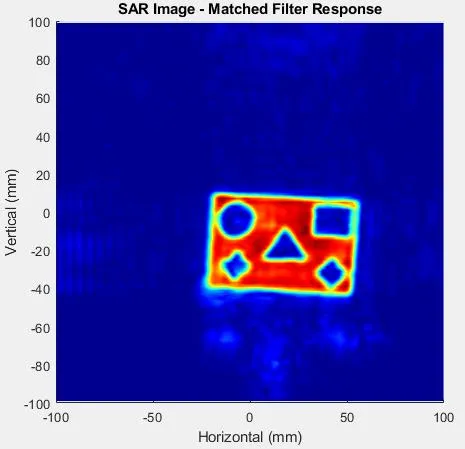

图9 2D成像结果

2-D imaging results of Two Flat 2-D Targets Concealed in Box Scenario are given in Figure 10. Two different slices are obtained by using two different range bins.

箱形场景中隐藏的两个平面二维目标的二维成像结果如图10所示。使用两个不同的范围容器可以获得两个不同的切片。

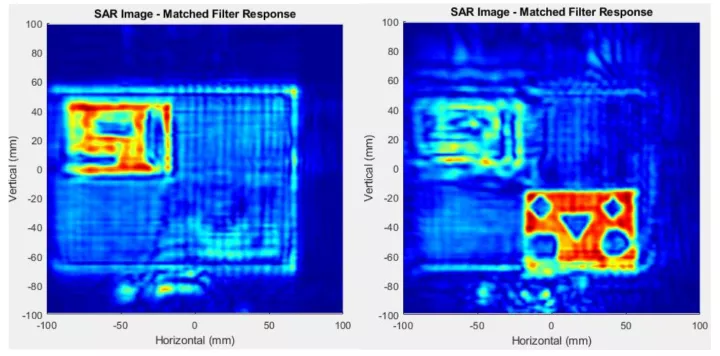

图10 两个平面二维目标隐藏在盒子场景图像结果(注:这些这是初步结果，将在3d成像后进行调整)

2-D imaging results of Cascaded Concealed Targets Scenario are given in Figure 11. Two different slices are obtained by using two different range bins.

级联隐藏目标场景的二维成像结果如图11所示。使用两个不同的范围容器可以获得两个不同的切片。

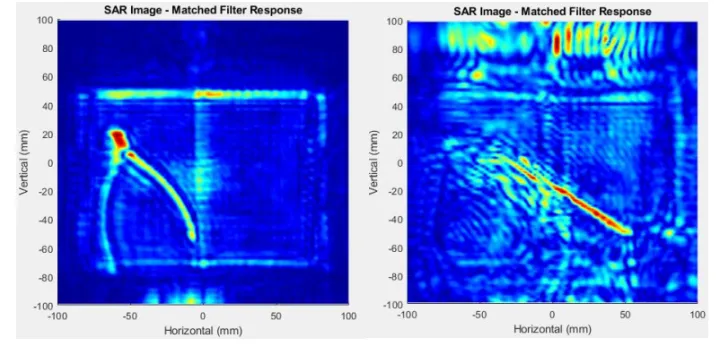

图11 级联隐蔽目标场景图像结果(注:这些是初步结果，将在三维成像后进行调整)